clc;
clear all;

% Choose modulation order and format
MOD_ORDER = 64;
% 
MODULATION_FORMAT = 'QAM';

NUM_SYMBOLS_PER_CARRIER = 1e4;

NUM_SUBCARRIERS = 15;

CYCLIC_PREFIX_LENGTH = 1/4; % Given as a ratio of symbol length

assert(mod((2+2*NUM_SUBCARRIERS)*CYCLIC_PREFIX_LENGTH,1) == 0);

% Create QAM modulated signal, given number of symbols we want to generate
[modulated_signal, symbol_stream] = generateRandModSignal(NUM_SYMBOLS_PER_CARRIER, MOD_ORDER, NUM_SUBCARRIERS, MODULATION_FORMAT);

% scatterplot(modulated_signal(:))

ofdm_signal = convertToOFDMSignal(modulated_signal, CYCLIC_PREFIX_LENGTH);


% plot(ofdm_signal);
% plot(autocorrelation(ofdm_signal, 300));
% xlim([66,300])

snr_ratios = linspace(1,20,50);
ber_vals = zeros(size(snr_ratios));

for index = 1:1:length(snr_ratios)
   ofdm_signal_with_noise = awgn(ofdm_signal,snr_ratios(index),'measured');
   extracted_modulated_signal = convertFromOFDMSignal(ofdm_signal_with_noise, NUM_SUBCARRIERS, CYCLIC_PREFIX_LENGTH);
   extracted_stream = demodSignal(extracted_modulated_signal, MOD_ORDER, MODULATION_FORMAT);
   [num_bit_errors, ber_vals(index), num_symbol_errors, symbol_error_rate] = calculateErrorRates(extracted_stream, symbol_stream);
end




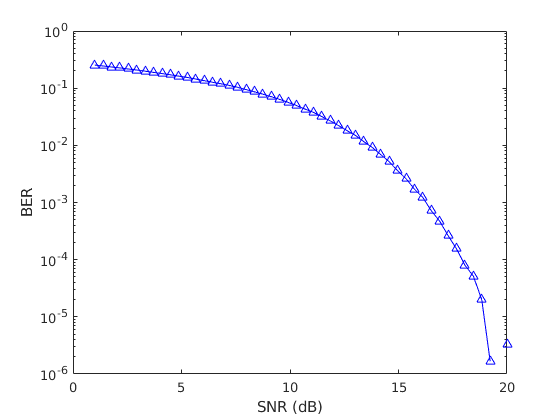


semilogy(snr_ratios, ber_vals, 'b-^')

xlabel('SNR (dB)')
ylabel('BER')